# **Vision Artificial. GIEC y GITT.**

# **	Sistemas de Vision Artificial. GIC, GII y GISI.**

**	Miguel Angel Garcia, Juan Manuel Miguel, Sira Palazuelos. **

**  Departamento de Electrónica. Universidad de Alcalá. SPAIN.**

# Tema 5: Kmeans (Unsupervised Learning)

## Primera parte

Nota: Se necesita tener instalada la Toolbox: "**statistics and Machine Learning**"

El objetivo de este ejercicio es hacer **agrupamiento** con **k-means **utilizando la base de datos  `fisheriris.mat`, que es un conjunto de datos de clasificación multiclase muy sencillo. Introducido por el estadístico y biólogo británico *Ronald Fisher* en su artículo de 1936. Contine 150 muestras, 50 muestras para cada una de las tres especies de flores Iris {`setosa, versicolor` y `virginica`}. Cada muestra contiene 4 características de las flores en el siguiente orden: 

- Longitud del sépalo.

- Anchura del sépalo.

- Longitud del pétalo.

- Anchura del pétalo

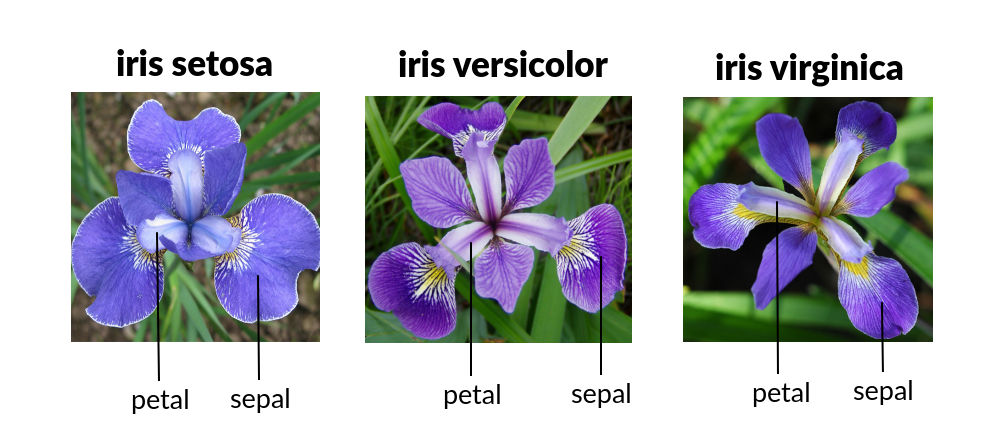

Los pasos que se deben realizar son:

- Cargar sólo la longitud y anchura del sépalo de la base de datos. 

- Visualizar los datos.

- Realizar el agrupamiento con el algoritmo k-Means.

- Visualizar el resultado del clustering.

Al cargar la base de datos` 'fisheriris'` (Se necesita tener instalada la Toolbox: "statistics and Machine Learning") se cargan las variables  `meas`, que contiene `[longitud sépalo, anchura sépalo, longitud pétalo, anchura pétalo] `en ese orden, y la variable `species`, que contiene la etiqueta de cada muestra. 

**Se pide:**

- Seleccione sólo la **longitud y anchura del sépalo** en la variable `'data_iris'` y muestre los resultados.

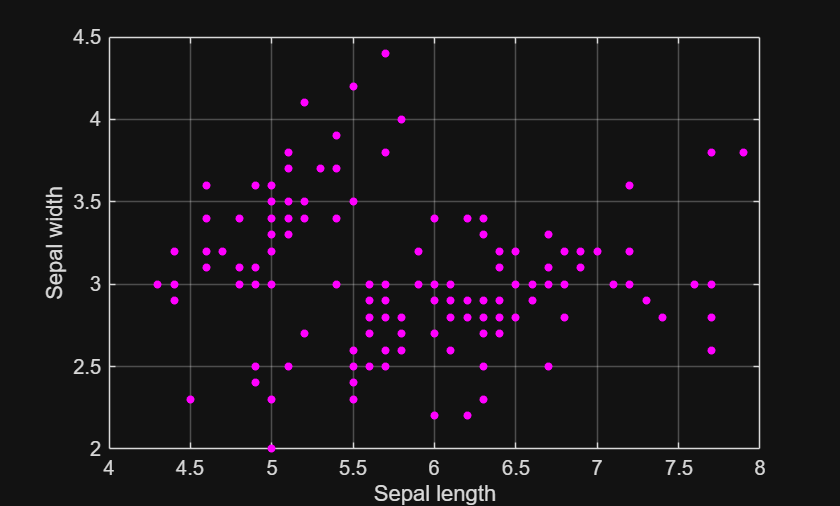

clear all;
close all;

% CARGAR LA BASE DE DATOS Y VISUALIZARLA

% carga las siguientes variables:
% meas: contiene los valores de las 150 muestras en el siguiente orden:
%       [longitud sépalo, anchura sépalo, longitud pétalo, anchura pétalo] 
% species: en un cell array con las 150 etiquetas de cada especie {setosa}, {versicolor} o {virginica}
load fisheriris % Se necesita tener instalada la Toolbox: "statistics and Machine Learning"

data_iris = meas(:, 1:2); % columnas 1 y 2 = sépalo

% visualiza los datos
figure
plot(data_iris(:,1), data_iris(:,2), '.', 'MarkerSize', 12, color='magenta')
xlabel('Sepal length'); ylabel('Sepal width'); grid on;

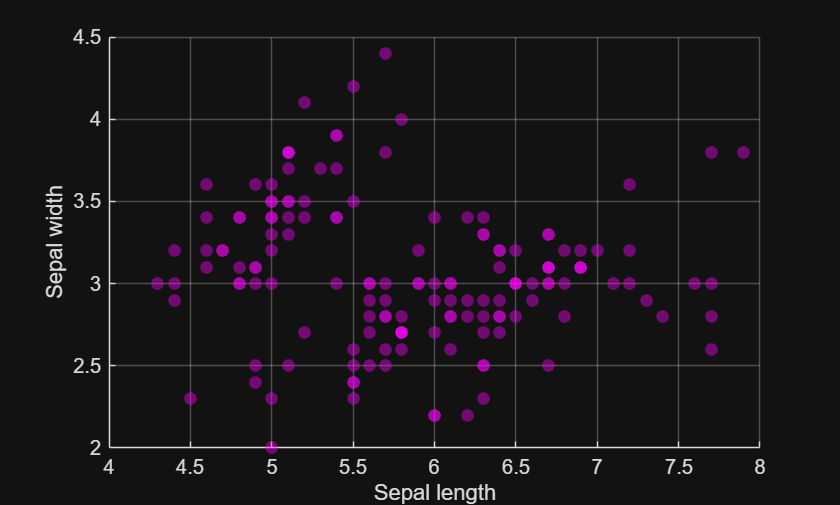


figure;
scatter(data_iris(:,1), data_iris(:,2), 40, 'magenta', 'filled', 'MarkerFaceAlpha', 0.4,'MarkerEdgeAlpha', 0.4);
xlabel('Sepal length');
ylabel('Sepal width');
grid on;

**Se pide:**

- Calcule los valores mínimos (`min_data_iris`) y máximos (`max_data_iris`) de la longitud y anchura del sépalo utilizando las funciones [`min` ](https://es.mathworks.com/help/matlab/ref/min.html?searchHighlight=min&s_tid=srchtitle_support_results_1_min)y [`max`](https://es.mathworks.com/help/matlab/ref/max.html?searchHighlight=max&s_tid=srchtitle_support_results_1_max) de Matlab.

- Calcule los K=3 centroides iniciales (`C_init)` con valores aleatorios (Utilice la función [`rand`](https://es.mathworks.com/help/matlab/ref/double.rand.html?s_tid=srchtitle_support_results_1_rand)) entre los mínimos y máximos calculados anteriormente.

- Dibuje los centroides iniciales sobre los datos de la longitud y anchura del sépalo cargados anteriormente.

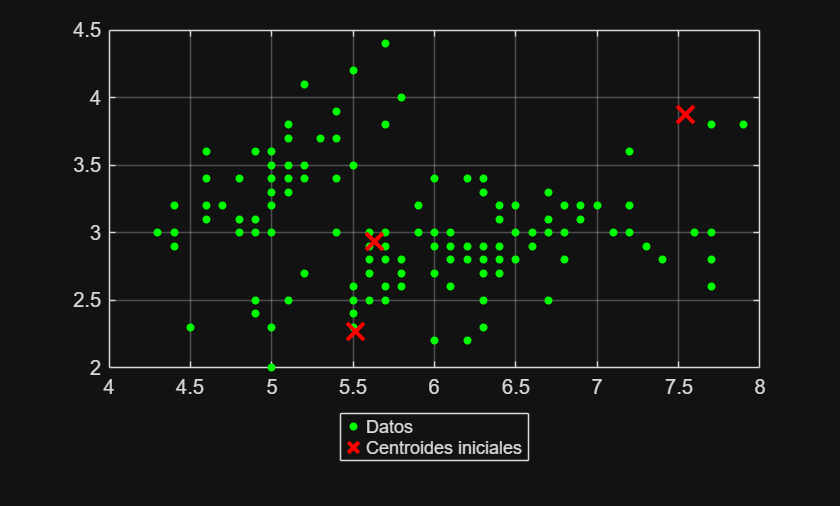

% clusters
k = 3; 

% valores máximos de la longitud y anchura del sépalo 
max_data_iris = max(data_iris); 

% valores minimos de la longitud y anchura del sépalo 
min_data_iris = min(data_iris); 

% valores iniciales para los centroides
rango = max_data_iris - min_data_iris;

% Generamos k puntos aleatorios entre 0 y 1 (con 2 coordenadas cada uno)
aleatorios = rand(k, 2);

% Escalamos esos puntos al tamaño de nuestros datos y los movemos al inicio real
C_init = min_data_iris + (aleatorios .* rango);

% Visualizar
figure
plot(data_iris(:,1), data_iris(:,2), 'g.', 'MarkerSize', 12)
hold on
plot(C_init(:,1), C_init(:,2), 'rx', 'MarkerSize', 12, 'LineWidth', 2)
hold off
legend('Datos', 'Centroides iniciales', 'Location', 'southoutside');
grid on;

**Se pide:**

- Ejecute el siguiente código que realiza el clustering utilizando la función [kmeans](https://es.mathworks.com/help/stats/kmeans.html) de Matlab.

- ¿Qué representan `'iter'`, `'num'`  y `'sum'`?.

- **iter**: el número de la iteración.

- **num**: cuántos puntos cambian de cluster en esa iteración.

- **sum**: la suma total de distancias (al cuadrado) de cada punto a su centroide. Es lo que k-means intenta minimizar, así que debería bajar en cada iteración.

- Ejecute varias veces el código cambiando los centroides inciciales y explique los resultados que obtiene el algoritmo k-means en cada iteración. 

- Los identificadores de cluster se asignan a conjuntos distintos

- el numero de iteraciones (iter) es distinto

- El num es distinto

- el sum total varia un poquito pero los centroides / clases acaban siendo practicamente iguales


% CLUSTERING
 
% k-Means
[idx, C, sumd, D] = kmeans(data_iris, k, 'Start', C_init, 'Display', 'iter');

  iter	 phase	     num	         sum
     1	     1	     150	     75.3029
     2	     1	      24	     60.9995
     3	     1	      24	     48.8141
     4	     1	      16	     39.0645
     5	     1	       7	     37.3036
     6	     1	       2	     37.0877
     7	     1	       1	     37.0507
Best total sum of distances = 37.0507


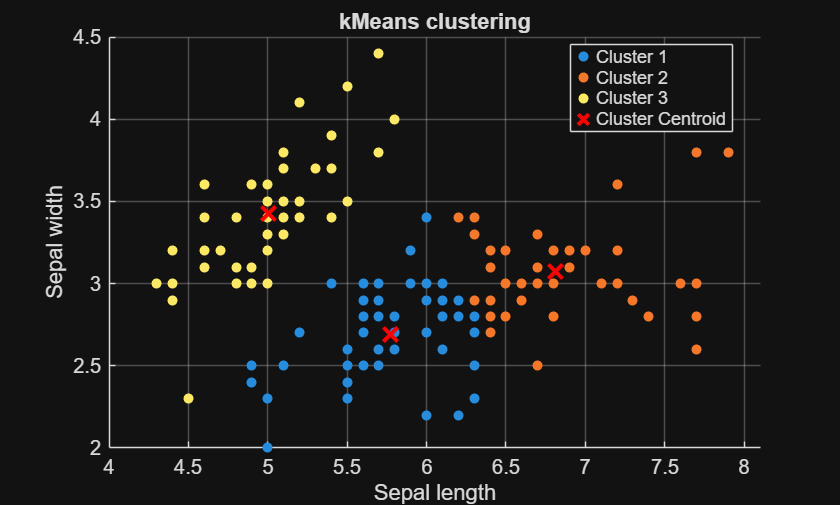


figure
gscatter(data_iris(:,1),data_iris(:,2),idx)
xlabel('Sepal length');
ylabel('Sepal width');
title('kMeans clustering');
hold on;
plot(C(:,1),C(:,2),'rx','MarkerSize',10, 'LineWidth',2)
legend('Cluster 1','Cluster 2','Cluster 3','Cluster Centroid');
hold off
grid;

    Hay que tener en cuenta que este es un algoritmo no supervisado por lo que los índices de salida (**idx**) no se corresponden con los nombres de las flores. Sin embargo, si queremos saber cómo de bien ha realizado el algorimto k-Means el agrupamiento debemos relacionar cada cluster con su etiqueta correspondiente. Sabemos que los datos de entrada (`data_iris`) están ordenados siguiendo la siguiente distribución: 

- Los datos del 1 al 50 son '`setosa`'.

- Los datos del 51 al 100 son '`versicolor`'.

- Los datos del 101 al 150 son '`virginica`'. 

    Para asignar cada índice con su correspondiente etiqueta se va a suponer que el clasificador k-means ha hecho un buen trabajo y el valor que más se repite (la moda) entre los primeros 50 datos es '`setosa`', en los siguientes 50 datos es '`versicolor`' y en los últimos 50 es '`virginica`'.

**Se pide:**

- Calcule la moda, con la función [mode](https://es.mathworks.com/help/matlab/ref/mode.html?searchHighlight=mode&s_tid=srchtitle_support_results_1_mode), de los índices que ha asignado k-means a los datos de entrada, teniendo en cuenta la distribución que se ha indicando anteriormente, asignando el índice correspiendiente a cada clase utilizando las variables: `setosa_idx, versicolor_idx o virginica_idx`. Ejecute el código y visualice el resultado.

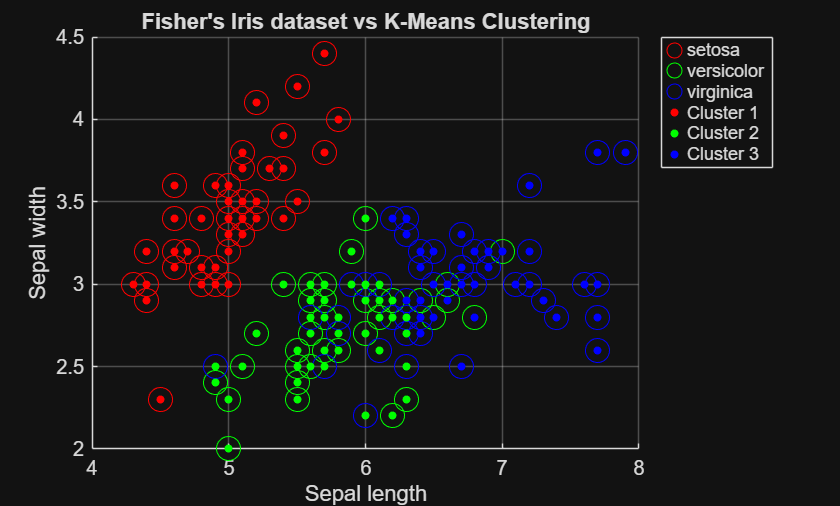

% Evaluación

setosa_idx = mode(idx(1:50));
versicolor_idx = mode(idx(51:100));
virginica_idx = mode(idx(101:150));

% Nombra las categorías haciendo coincidir los valores de categoría en [setosa_idx versicolor_idx virginica_idx]
% con los nombres correspondientes en {'setosa' 'versicolor' 'virginica'}.
label_kmeans = categorical(idx,[setosa_idx versicolor_idx virginica_idx],{'setosa' 'versicolor' 'virginica'});

% Fisher''s Iris dataset
figure;
hold on

% setosa
plot(data_iris(1:50,1),data_iris(1:50,2),'ro','MarkerSize',12)
% versicolor
plot(data_iris(51:100,1),data_iris(51:100,2),'go','MarkerSize',12)
% virginica
plot(data_iris(101:150,1),data_iris(101:150,2),'bo','MarkerSize',12)
% k-means
plot(data_iris(idx==setosa_idx,1),data_iris(idx==setosa_idx,2),'r.','MarkerSize',12)
plot(data_iris(idx==versicolor_idx,1),data_iris(idx==versicolor_idx,2),'g.','MarkerSize',12)
plot(data_iris(idx==virginica_idx,1),data_iris(idx==virginica_idx,2),'b.','MarkerSize',12)

xlabel('Sepal length');
ylabel('Sepal width');
hold off

grid on;
legend('setosa','versicolor', 'virginica', 'Cluster 1','Cluster 2','Cluster 3','Location','bestoutside')
title ('Fisher''s Iris dataset vs K-Means Clustering')

**Se pide:**

- Calcule la matriz de confusión del algoritmo K-means usando la función [confusionmat](https://es.mathworks.com/help/stats/confusionmat.html?searchHighlight=confusionmat&s_tid=srchtitle_support_results_1_confusionmat) y guarde el valor en la variable `CM_kmeans`, utilice esta matriz para calcular la precisión (accuracy) y guardela en la variable `ACC1`. 

- Por último, cambie los datos de entrada por la** longitud y anchura de los pétalos **y vuelva a ejecutar todo el código, guardando la precisión (accuracy) en la variable `ACC2` y compárela con `ACC1`, ¿cuál es mejor?

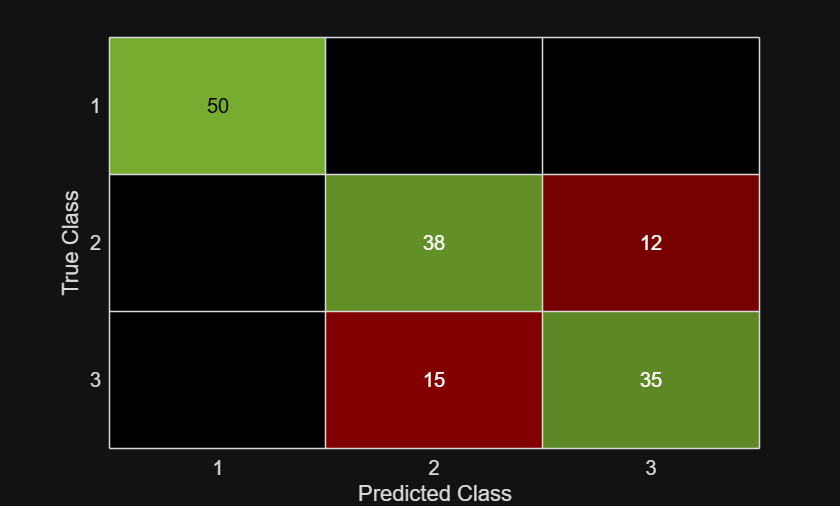

CM_kmeans = confusionmat(categorical(species), label_kmeans);
figure
confusionchart(CM_kmeans, 'DiagonalColor', [0.4660 0.6740 0.1880], 'OffDiagonalColor','red');

ACC1 = sum(diag(CM_kmeans)) / sum(CM_kmeans(:)); % guardar con sepalos


%% Repetir todo con el petalo -> ACC2

% Datos: columnas 3 y 4 = longitud y anchura del pétalo
data_iris = meas(:, 3:4);

% Centroides iniciales aleatorios
max_data_iris = max(data_iris);
min_data_iris = min(data_iris);
C_init = min_data_iris + rand(k, 2) .* (max_data_iris - min_data_iris);

% k-Means
[idx, C] = kmeans(data_iris, k, 'Start', C_init, 'Display', 'iter');

  iter	 phase	     num	         sum
     1	     1	     150	     86.2316
     2	     1	      13	     59.4134
     3	     1	      15	      41.837
     4	     1	      11	     33.8404
     5	     1	       4	     32.3814
     6	     1	       3	     31.7301
     7	     1	       2	     31.5178
     8	     1	       1	     31.4827
     9	     1	       1	     31.4129
Best total sum of distances = 31.4129


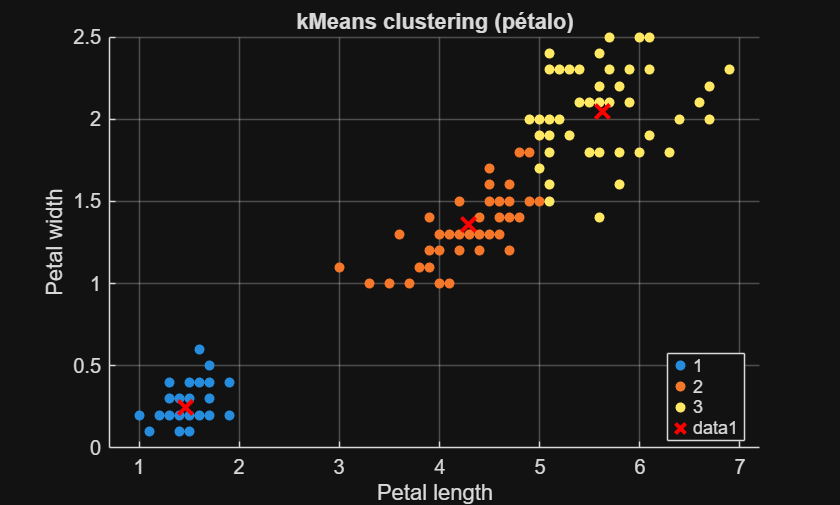


figure
gscatter(data_iris(:,1), data_iris(:,2), idx)
hold on
plot(C(:,1), C(:,2), 'rx', 'MarkerSize', 10, 'LineWidth', 2)
hold off
xlabel('Petal length');
ylabel('Petal width');
title('kMeans clustering (pétalo)');
grid on;

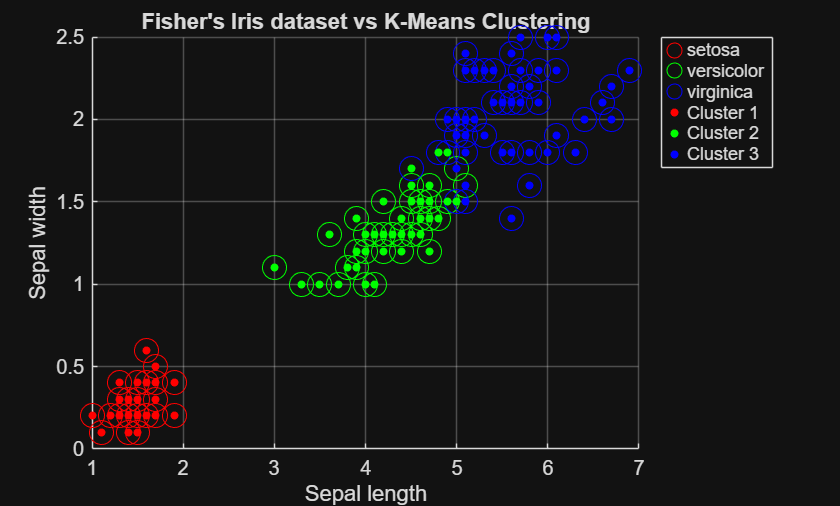


% Asociar cada cluster con su flor (moda)

% Evaluación
setosa_idx = mode(idx(1:50));
versicolor_idx = mode(idx(51:100));
virginica_idx = mode(idx(101:150));

% Nombra las categorías haciendo coincidir los valores de categoría en [setosa_idx versicolor_idx virginica_idx]
% con los nombres correspondientes en {'setosa' 'versicolor' 'virginica'}.
label_kmeans = categorical(idx,[setosa_idx versicolor_idx virginica_idx],{'setosa' 'versicolor' 'virginica'});

% Fisher''s Iris dataset
figure;
hold on

% setosa
plot(data_iris(1:50,1),data_iris(1:50,2),'ro','MarkerSize',12)
% versicolor
plot(data_iris(51:100,1),data_iris(51:100,2),'go','MarkerSize',12)
% virginica
plot(data_iris(101:150,1),data_iris(101:150,2),'bo','MarkerSize',12)
% k-means
plot(data_iris(idx==setosa_idx,1),data_iris(idx==setosa_idx,2),'r.','MarkerSize',12)
plot(data_iris(idx==versicolor_idx,1),data_iris(idx==versicolor_idx,2),'g.','MarkerSize',12)
plot(data_iris(idx==virginica_idx,1),data_iris(idx==virginica_idx,2),'b.','MarkerSize',12)

xlabel('Sepal length');
ylabel('Sepal width');
hold off

grid on;
legend('setosa','versicolor', 'virginica', 'Cluster 1','Cluster 2','Cluster 3','Location','bestoutside')
title ('Fisher''s Iris dataset vs K-Means Clustering')

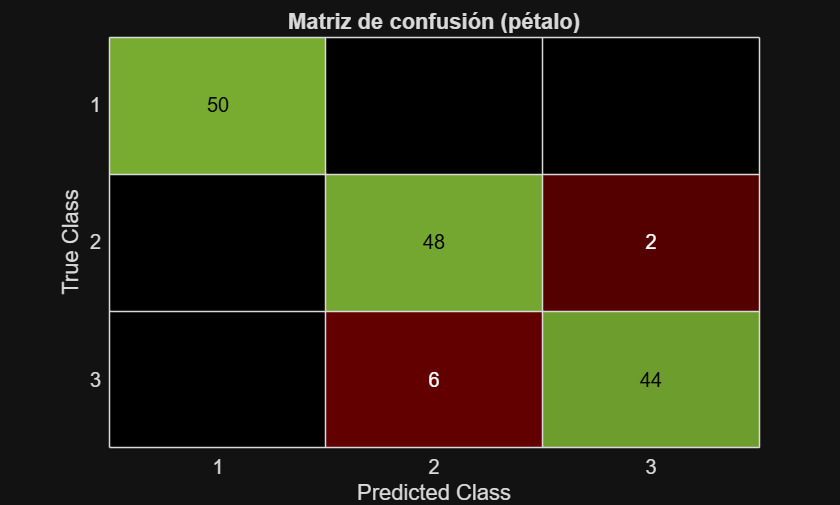


% Matriz de confusión y precisión
CM_kmeans2 = confusionmat(categorical(species), label_kmeans);
figure
confusionchart(CM_kmeans2, 'DiagonalColor', [0.4660 0.6740 0.1880], 'OffDiagonalColor','red');
title('Matriz de confusión (pétalo)');


ACC2 = sum(diag(CM_kmeans2)) / sum(CM_kmeans2(:));

% Comparación
disp(['ACC1 (sépalo) = ', num2str(ACC1)]);

ACC1 (sépalo) = 0.82


disp(['ACC2 (pétalo) = ', num2str(ACC2)]);

ACC2 (pétalo) = 0.94667
